Fie $E_n = \int_{0}^{1}{x^ne^{x-1}dx}$. Se observa ca:

- $E_1 = \frac{1}{e}$;

- $E_n = 1 - n * E_{n-1}, n > 1$;

Se poate arăta că: $0 < E_n < \frac{1}{n+1}$, iar daca avem $E_1 = c \Rightarrow \lim_{n \rightarrow \infty}E_n =$

- $0, c = \frac{1}{e}$;

- $\infty, altfel$;

**Explicați fenomenul, găsiți un remediu și calculați e cu precizia eps**.

Pare ca formula de recurenta $E_n = 1 - n * E_{n-1}$ este **prost conditionata**, fapt ce poate fi demonstrat prin **analiza efectului perturbarii primului termen al seriei recurente cu un factor mic **$\delta$.

$\delta_n = E_n^p - E_n$, $E_n^p = 1 - n * E_{n-1}^p$, $E_n = 1 - n*E_{n-1}$


$$\delta_n = (1 - n * E_{n-1}^p) - (1 - n * E_{n-1}) = -n * (E_{n-1}^p - E_{n-1})$$



$$\delta_{n-1} = E_{n-1}^p - E_{n-1}$$


$\Rightarrow \delta_n = -n * \delta_{n-1}: \delta_2 = -2 * \delta_1 \Rightarrow \delta_3 = 6 * \delta_1 \Rightarrow \delta_4 = -24 * \delta_1 \Rightarrow ... \Rightarrow \delta_n = n! * \delta$, intuitiv.

Astfel, se poate observa ca **respectand seria recurenta** si **avand o perturbare mica** a lui $E_1 = \frac{1}{e}$, ***eroarea creste factorial***, sugerand un **numar de conditionare ****FOARTE**** mare**, conducand la o *divergenta catastrofica a rezultatului*.

Un **remediu** ar fi calculul rezultatului in mod direct folosind integrala data.

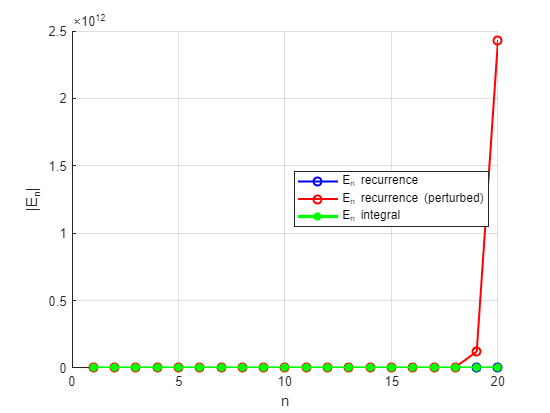

% vom analiza efectul perturbarii primului termen in acuratetea formulei
% seriei recurente
num_terms = 20;
perturbation_term = 1e-6;

E1 = 1/exp(1);

En_rec = zeros(1, num_terms);
En_rec_perturbed = zeros(1, num_terms);
En_integral = zeros(1, num_terms);

% seria recurenta
En_rec(1) = E1;
En_rec_perturbed(1) = E1 + perturbation_term;

for i = 2:num_terms
    En_rec(i) = 1 - i * En_rec(i - 1);
    En_rec_perturbed(i) = 1 - i * En_rec_perturbed(i - 1);
end

% integrala
for i = 1:num_terms
    int_ = @(x) x.^i .* exp(x - 1);
    En_integral(i) = integral(int_, 0, 1);
end

figure(1);
hold on;

semilogy(1:num_terms, abs(En_rec), 'bo-', 'LineWidth', 1.5, 'DisplayName', 'E_n recurrence');
semilogy(1:num_terms, abs(En_rec_perturbed), 'ro-', 'LineWidth', 1.5, 'DisplayName', 'E_n recurrence (perturbed)');
semilogy(1:num_terms, abs(En_integral), 'g*-', 'LineWidth', 2.5, 'Displayname', 'E_n integral');

legend('Location', 'best');
grid on;
xlabel('n');
ylabel('|E_n|');
hold off;

Se poate observa cum recurenta ***explodeaza*** cand $E_1 \ne \frac{1}{e}$.

Folosim formula de recurenta, dar in sens invers Pentru a calcula **e **cu precizia, cunoastem faptul ca $0 < E_n < \frac{1}{n+1}$; luand $\frac{1}{n+1}$ ca o **margine superioara**, calcula **e **cu precizia ***eps ***daca $\frac{1}{n+1} < eps$.


$$E_1 = \frac{1}{e} \Rightarrow e = \frac{1}{E_1}$$


Stiind ca seria converge la 0 cand $E_1 = \frac{1}{e}$, putem presupune ca $E_n \approx 0$, luand o valoare foarte apropiata de 0.

% am avea nevoie de un n foarte mare, insa iterativ ar lua prea mult
% luam un n arbitrar, mai mic
n = 10^6;
% stiind ca seria converge la 0 cand E1 = 1/e, putem presupune ca E_n
E_next = 0.0;
E_prev = 0.0;

% E_{n-1} = (1-E_n)/n
while n > 1
    E_prev = (1-E_next) / n;
    E_next = E_prev;
    n = n - 1;
end

% e = 1/E1
exp_ = 1/E_prev;
abs_err = abs(exp_ - exp(1));
fprintf("### e = %.16e | e (calculat) = %.16e | ABSOLUTE ERROR: %.16e\n\n", exp(1), exp_, abs_err);

### e = 2.7182818284590455e+00 | e (calculat) = 2.7182818284590451e+00 | ABSOLUTE ERROR: 4.4408920985006262e-16

